clc; clear all; close all;

recon_x=128; recon_y=256;
sigma=3; mu=0;
%fourierSigma=sqrt(recon_x*recon_y)/sigma
fourierSigma=1/sqrt(recon_x*recon_y*sigma^2)

fourierSigma = 0.0018

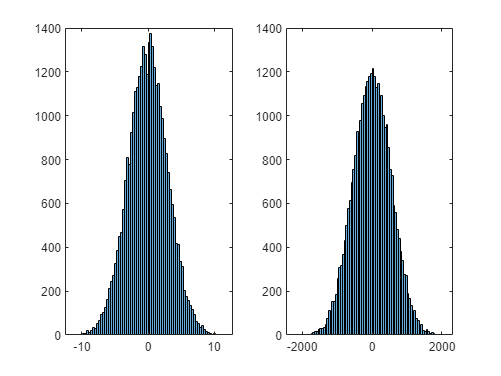


imageSpace = sigma*randn(recon_y,recon_x)+sigma*randn(recon_y,recon_x)*sqrt(-1);
fourierSpace = fft2(imageSpace);

figure;
subplot(1,2,1)
histogram(real(imageSpace(:)))
subplot(1,2,2)
histogram(real(fourierSpace))


realSigmaI = std(real(imageSpace(:)))

realSigmaI = 2.9913

imagSigmaI = std(imag(imageSpace(:)))

imagSigmaI = 2.9914


realSigmaF = std(real(fourierSpace(:)))

realSigmaF = 542.2072

imagSigmaF = std(imag(fourierSpace(:)))

imagSigmaF = 540.7593


realSigmaI/realSigmaF

ans = 0.0055

imagSigmaI/imagSigmaF

ans = 0.0055


(sigma/fourierSigma)

ans = 1.6292e+03


(sigma/fourierSigma)/imagSigmaI/imagSigmaF % should be 1 if I got fourierSigma correct

ans = 1.0071

## test epoch generation

epochs=12;
rest=5;
task=5;
repmat([zeros(rest,1);ones(task,1)],epochs,1)

ans =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1
